# Full Wave Simulator

Converts LTSPICE .txt files to a MATLAB Matrix and plots

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types


%cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
cd 'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1'
addpath( 'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
    'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1',...
    'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter', ... % LT Spice reader from Github
    'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
    'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\Export',...
    'G:\My Drive\Code\COMSOL', ...
    'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\SMA Injection'...
); %new comsol stuff


load('ImpVariables.mat')

## Generate and Fit Impedance Response of Load

% Workbook for impedance math in "C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1"
% Result is plotted
clf
port = ImportCOMSOL_Z('Kimball_Impedance.txt');
yyaxis left
loglog(port.freq, abs(port.z))
yyaxis right
semilogx(port.freq, unwrap(angle(port.z)),'LineStyle',"--");
title('Impedance at Port')
hold off

ratFitS = rationalfit(port.freq, port.s11);
generateSPICE(ratFitS, 'JWS_TestNetwork_v0.ckt');


## Check Converted Impedance Response 

**IMPORTING  -** Two Columns, Export using Log Scale (Ohm) and [f, Re1, Im1, Re2, Im2] parts

clf
figure()
filenameAdd = '200825 xGAN xGEM Freq Response.txt';
freqSample = 10;

Data = LT_Freq2Table(filenameAdd);
Data = table2array(Data);
Data = str2double(Data);

FreqSweepVect = Data(:,1);
Re1 = Data(:,2);
Im1 = Data(:,3);
Z1 = (Re1.^2 + Im1.^2).^0.5;
Re2 = Data(:,4);
Im2 = Data(:,5);
Z2 = (Re2.^2 + Im2.^2).^0.5;


loglog(port.freq, abs(port.z), 'LineWidth', 1.5) %, 'Color', 'black')
set(gcf, 'Position', [0 0 400 300]);
hold on
loglog(FreqSweepVect, Z1, 'LineStyle',"--") %, 'Color', 'black')
loglog(FreqSweepVect, Z2, "LineStyle","--") %, 'Color', 'black')
title('Impedance of Load and RLC Equivalent')
ylabel({'Impedance Magnitude (\Omega)'});
xlabel({'Frequency (Hz)'});
legend('Full Impedance Response', 'RLC Approximate Response', 'Fit Impedance Response', 'Location', 'northwest')
xlim([1e8,1e10])
ylim([1e-2 1e5])
annotation('arrow',[0.5696 0.7071],[0.7143 0.4571])
annotation('textarrow',[0.6036 0.6732],[0.7262 0.6595],'String','Higher Order Resonances')
annotation('textarrow',[0.4875 0.55],[0.3809 0.2809],'String','First Resonance')
annotation('textarrow',[0.2929 0.2],[0.6548 0.6],'String','Capacitive Fit')
hold off
C_eff = 1/(2*pi*port.freq(freqSample)*abs(port.z(freqSample)))

resFreq = 1.42e9; %GHz
% w^2 = 1/LC
L_eff = 1/((2*pi*resFreq)^2*C_eff)

## Import COMSOL Transfer Function 

filename = 'portVoltage.txt'
data1=readtable(filename,'HeaderLines',5);
data1=table2array(data1);
port.freq = data1(:,1);
port.v = data1(:,2);

filename='xField_ProbePoints.txt';
makeSymmetric = 1;
freq = port.freq;
%[rawTF, symTF] = ImportCOMSOL_TF(filename, port.v, makeSymmetric);
%[trFnRawGrid, trFnSymmetricGrid] = ImportCOMSOL_TFgrid(filename, portVoltage, makeSymmetric)
    data2=readtable(filename,'HeaderLines',9);
    %data=table2array(data);
    sizeArr = size(data2);
    sizeArr = sizeArr(1,1);
    % NO DC TERM IN RAW!
    %freq = freq.min:freq.step:freq.max;
    for(ii = 1:numPts)
        trFnRaw(ii).x = (data2(:,1)).';
        trFnRaw(ii).y = (data2(:,2)).';
        trFnRaw(ii).z = (data2(:,3)).';
        trFnRaw(ii).fieldTF = (data2(:,4:end)./port.v).';
    end
    %Default state of mirror!
    
    if (makeSymmetric)
        comsolFreqStep=trFnRaw.freq(1,2)-trFnRaw.freq(1,1);
        posFreq=trFnRaw.freq;
        negFreq=-1*flip(posFreq);
        % Ordering of FFT is 0-Pos-Neg
        trFnSymmetric.freq = [0,posFreq,negFreq]; %add DC term!

        mirrorTFpos=(trFnRaw.fieldTF);%/length(posFreq);
        mirrorTFneg=flip(conj(mirrorTFpos)); %new side conjugate symmetric!!
        trFnSymmetric.fieldTF = [0, mirrorTFpos, mirrorTFneg]; %setting DC term to 0! AC coupling...
    end

## Import Try 2

filename = 'portVoltage.txt';
data1=readtable(filename,'HeaderLines',5);
data1=table2array(data1);
port.freq = data1(:,1);
port.v = data1(:,2);
    
filename = 'xField_sidePlane_grid.txt'
data=readtable(filename,'HeaderLines',9);
data=table2array(data);
propField.x = data(:,1);
propField.y = data(:,2);
propField.z = data(1,3);
propField.Ex = data(:,4:end).';

pointsize = 100;
fieldPlot = abs(propField.Ex(1,:)/propField.Ex(1,1)); % Normalized electric field at 50 MHz normalized to a corner


scatter3(real(propField.y(:)), real(propField.x(:)), fieldPlot , pointsize, fieldPlot, '.') 
view([0 90]);
shading interp;


## Figure out points

index1 = (6561-1)*0.5+1;
propField.x(index1)
propField.y(index1)
index2 = (6561-1)*0.5+41;
propField.x(index2)
propField.y(index2)
index3 = (6561-1)*15/16+47;
propField.x(index3)
propField.y(index3)
index4 = (6561-1)*15/16+87;
propField.x(index4)
propField.y(index4)

xFeild = data([index1, index2, index3, index4],4:end).';
portVolt = (port.v);

## Convert and Export

normField = zeros(200, 4);
normField(:,1) = xFeild(:,1)./portVolt;


## OG TF Math

## Convert COMSOL Transfer Function 

filename='NormTF_SMA_InputLarge_MirrorCenterOffset.txt';
makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, 1, makeSymmetric);

clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Field Transfer Function");
hold off
clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Field Transfer Function");
hold off

## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

name = '200825 xGAN Kimball Circuit Resetting.txt';
timeRes = 1/20e9; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear
[stepR,interpTime, interpVoltAll] = ImportLTSpiceSweep(name, timeRes, interpMethod);
% ADD LTSPICE SIM NOTES

% Plots out result read from file to check
figure()
plot(interpTime/c.nano, interpVoltAll, "LineWidth", 1.5); xlabel('Time (ns)'); ylabel('Voltage (V)'); title('Port Voltage with Varying Resistances')
rNames = string(stepR);
legend('R=' + rNames +'\Omega')
%xlim([0 10])
save("200825 xGAN Kimball Circuit Resetting.mat", "stepR", "interpTime", "interpVoltAll");

## Generate and Plot LTSpice Output FT

% clf;

% [time, signal, freq, fftSignal] = inputFunction('gEdge', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),100e15);
% plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")
% %xlim([0,10])
% 
% %Compares steps
% % for resIndexTemp = 1:9
% %     [time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndexTemp,:));
% %     loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1)/abs(fftSignal(1)))); 
% %     xlabel("Frequency"); ylabel("Amplitude"); title('Pulse in Frequency Domain')
% %     hold on
% % end
% % xlim([5e8 1e10])
% % hold off


## Combine and Plot Output

clf
resIndex = 6;
%tiledlayout(2,2);
stepR(resIndex);
[time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),0, 0);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")

% Plot FFT Original
loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

% Plot Final Result
outputSignal = ifft(outputFFT); 
plot(time/c.nano, outputSignal);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
grid minor;
xlim([0,5])


## Plot Multiple Outputs

%Compares steps
clf;
%SelectedTraces = [1, 10, 25, 50]
%outputSignalAll = zeros(9,2001);
for resIndexTemp = 1:9
    [time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndexTemp,:), 0, 0);
    
    outputFFT = fftSignal.*symTF.fieldTF;
    outputSignalAll(resIndexTemp,:) = ifft(outputFFT); 
end
outputSignalRescaled = (outputSignalAll-outputSignalAll(1,1))/outputSignalAll(1,1)*0.22;
plot(time/c.nano, outputSignalRescaled, 'LineWidth',1.5);
%title('Field in Mirror Time Domain'); 
xlabel("Time (ns)"); ylabel("Scaled Field in Mirror (V/m)");
legend('R_{damp} = ' + rNames +'\Omega')
%legend("Ideal Gaussian Response")
xlim([0,5])
%ylim([-1.1, -0.9])


## Plot Step Function

% clf
% stepR(resIndex);
% [time, signal, freq, fftSignal] = inputFunction('Heaviside', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),1000, -1030);
% % Plot Original Time
% plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); xlim([0 5])
% 
% % Plot FFT Original
% % loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')
% 
% % Plot Mixed Signal
% outputFFT = fftSignal.*symTF.fieldTF;
% %loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')
% 
% % Plot Final Result
% outputSignal = ifft(outputFFT); 
% outputSignalRescaled = ((outputSignal+180)/320); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
% plot(time/c.nano, outputSignalRescaled);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
% title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
% xlim([0,5])
% %erfOutput = outputSignalRescaled-1;
% %erfTime = time;
% %ylim([0 0.01])

## Plot Step with Error Function

clf
[time, signal, freq, fftSignal] = inputFunction('ErrorFn', 1/20e9, 50*c.mega,  interpTime, interpVoltAll(resIndex,:),1000, -880);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); xlim([0 5])

% Plot FFT Original
loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

% Plot Final Result
outputSignal = ifft(outputFFT); 
scaleShift = 270;
outputSignalRescaled_fastest = ((outputSignal+scaleShift)/(2*scaleShift)); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
plot(time/c.nano, outputSignalRescaled_fastest);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
xlim([0,5])
%erfOutput = outputSignalRescaled-1;
%erfTime = time;
%ylim([0 0.01])


## Convert COMSOL Transfer Function 

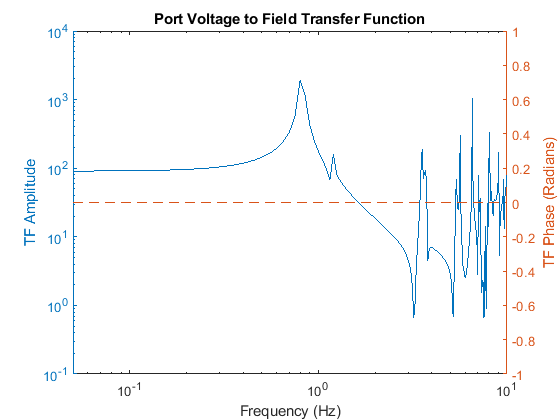

%filename='NormTF_SMA_InputLarge_MirrorCenterOffset.txt';
filename = 'NormTF_SMA_InputLarge_gndBnc.txt';
%filename='NormTF_SMA_InputLarge_MirrorCenter.txt';

makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, 1, makeSymmetric);

clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Field Transfer Function");
hold off

clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Field Transfer Function");
hold off

## Plot Slow Error Function (Ideal) Response

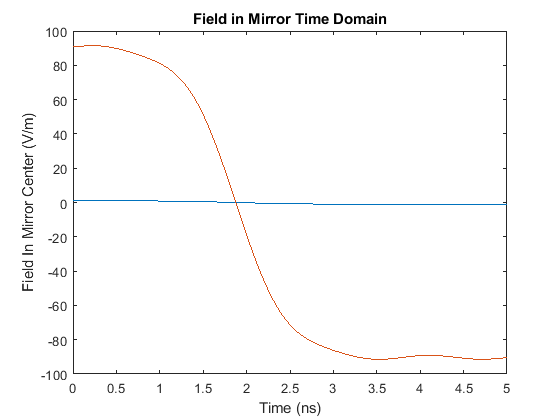

clf

[time, signal, freq, fftSignal] = inputFunction('ErrorFn', 1/20e9, 50*c.mega,  interpTime, interpVoltAll(resIndex,:),6.05, -865);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); xlim([0 10])

% Plot FFT Original
% loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
%loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

% Plot Final Result
outputSignal = ifft(outputFFT); 
outputSignalRescaled_medium = (outputSignal); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
figure (1)
hold on
plot(time/c.nano, outputSignalRescaled_medium);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
xlim([0,5])
hold off

%erfOutput = outputSignalRescaled-1;
%erfTime = time;
%ylim([0 0.01])

save.gndBnc = outputSignalRescaled_medium

save = struct with fields:
       center: [1×401 double]
    centerOff: [1×401 double]
       gndBnc: [1×401 double]


## Gaussian Filter Response

## Plot Slow Error Function (Ideal) Response

clf

[time, signal, freq, fftSignal] = inputFunction('GaussFilt', 1/20e9, 50*c.mega,  interpTime, interpVoltAll(resIndex,:),1.2*1e4, -150);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("Ideal Port Voltage"); %xlim([0 5])

% Plot FFT Original
%loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
%loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

% Plot Final Result

outputSignal = ifft(outputFFT); 
outputSignalRescaled_gfilt = (rescale(outputSignal)); %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
plot(time/c.nano, outputSignalRescaled_gfilt);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
xlim([0,5])

## Combine into final plot

clf;
tiledlayout(2,1)
nexttile
plot( ...
    time/c.nano, circshift(outputSignalRescaled_fastest, -7), "LineWidth",1)
xlim([0 5]);
xlabel('Time (ns)')
ylabel('Electric Field (norm.)')
legend('50 ps Step Response')

nexttile
plot( ...
    time/c.nano, circshift(outputSignalRescaled_medium,-7), ...
    time/c.nano, circshift((outputSignalRescaled(7, :)+1), 993), ...
    'linewidth', 1)%, time/c.nano, outputSignalRescaled_gfilt);
xlim([0 5]);
ylim([-0.1 1.1])
xlabel('Time (ns)')
ylabel('Electric Field (norm.)')
legend('Gaussian Response (1% Ringing)', 'RLC Response', '50 ps Step Response')


## Plot

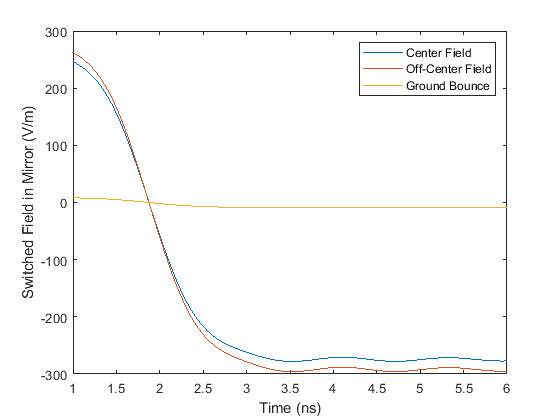

plot(time/c.nano, save.centerOff, time/c.nano, save.center, time/c.nano, save.gndBnc/10)
xlabel('Time (ns)')
ylabel('Switched Field in Mirror (V/m)')
legend('Center Field', 'Off-Center Field', 'Ground Bounce')
xlim([1,6])